# Drive mobile robot to a pose

Copyright (C) 1993-2018, by Peter I. Corke, [http://www.petercorke.com](http://www.petercorke.com)

We will show how to make a mobile robot with "car-like" steering drive from one pose to another.

The goal pose is

xg = [5 5 pi/2];

and the starting pose is

x0 = [5 9 0]

x0 =      5     9     0


We use a Simulink model to represent the dynamics of the vehicle and to implement a pose controller

sl_drivepose

We run the simulation

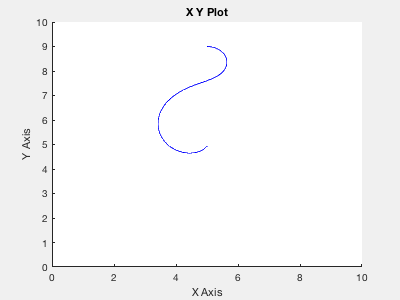

alpha -1.570796, beta 1.570796
going forwards


r = sim('sl_drivepose');

and extract the trajectory of the robot

y = r.find('y')

y =     5.0000    9.0000         0
    5.0001    9.0000   -0.0002
    5.0008    9.0000   -0.0012
    5.0040    9.0000   -0.0062
    5.0201    8.9997   -0.0313
    5.0700    8.9962   -0.1092
    5.1194    8.9888   -0.1871
    5.1681    8.9776   -0.2650
    5.2158    8.9626   -0.3428
    5.2622    8.9440   -0.4207


which we plot

clf; axis([0 10 0 10]); hold on; grid on
plot(y(:,1), y(:,2));

and overlay the initial and final pose of the robot

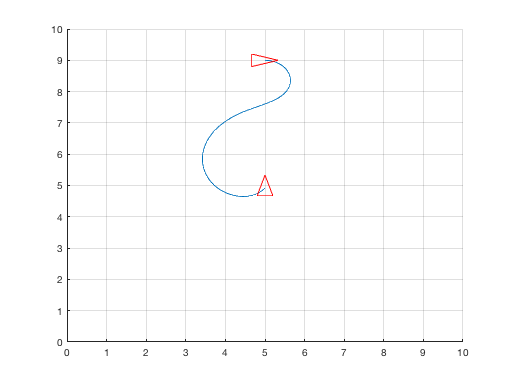

plot_vehicle(x0, 'r'); plot_vehicle(xg, 'r');

Note the complex path the robot had to follow, since it's motion is limited by the nature of the steering mechanism.